% Definisco i parametri
M = 0.5;
m = 0.3;
L = 1;
g = 9.81;

% Definizione matrici
A = [0, 1, 0, 0;
     0, 0, -m*g/M, 0;
     0, 0, 0, 1;
     0, 0, (M+m)*g/(M*L), 0]

A =          0    1.0000         0         0
         0         0   -5.8860         0
         0         0         0    1.0000
         0         0   15.6960         0


B = [0; 1/M; 0; -1/(M*L)]

B =      0
     2
     0
    -2


C = [1, 0, 0, 0;
     0, 0, 1, 0]

C =      1     0     0     0
     0     0     1     0


D = [0; 0]

D =      0
     0


sys_ol = ss(A,B,C,D)

sys_ol =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2       0       0  -5.886       0
   x3       0       0       0       1
   x4       0       0    15.7       0
 
  B = 
       u1
   x1   0
   x2   2
   x3   0
   x4  -2
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



eig(sys_ol)

ans =          0
         0
    3.9618
   -3.9618


% verifica controllabilità ed osservabilità
if rank(ctrb(A,B)) == length(A)
    disp("controllabile")
else
    disp("non completamente controllabile")
end

controllabile



if rank(obsv(A,C)) == length(A)
    disp("osservabile")
else
    disp("non completamente osservabile")
end

osservabile


% LQR
R = 1/50

R = 0.0200

Q = C'*C

Q =      1     0     0     0
     0     0     0     0
     0     0     1     0
     0     0     0     0


[K, S, CLP] = lqr(sys_ol,Q,R)

K =    -7.0711   -7.4996  -46.8629  -13.8077


S =     1.0606    0.5624    1.9527    0.6332
    0.5624    0.3975    1.4379    0.4725
    1.9527    1.4379    6.1392    1.9065
    0.6332    0.4725    1.9065    0.6105


CLP =   -2.2134 + 1.3016i
  -2.2134 - 1.3016i
  -4.0947 + 2.0677i
  -4.0947 - 2.0677i



sys_cl = ss(A-B*K,B,C,D)

sys_cl =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2   14.14      15   87.84   27.62
   x3       0       0       0       1
   x4  -14.14     -15  -78.03  -27.62
 
  B = 
       u1
   x1   0
   x2   2
   x3   0
   x4  -2
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



x0 = [0.4, 0, 0.4, 0];
[Y, T, X] = initial(sys_cl, x0)

Y =     0.4000    0.4000
    0.4082    0.3926
    0.4307    0.3726
    0.4645    0.3430
    0.5068    0.3062
    0.5555    0.2644
    0.6084    0.2194
    0.6640    0.1726
    0.7208    0.1255
    0.7776    0.0789


T =          0
    0.0208
    0.0416
    0.0624
    0.0832
    0.1040
    0.1248
    0.1456
    0.1664
    0.1873


X =     0.4000         0    0.4000         0
    0.4082    0.7644    0.3926   -0.6833
    0.4307    1.3740    0.3726   -1.2145
    0.4645    1.8479    0.3430   -1.6153
    0.5068    2.2036    0.3062   -1.9047
    0.5555    2.4569    0.2644   -2.0997
    0.6084    2.6220    0.2194   -2.2153
    0.6640    2.7116    0.1726   -2.2649
    0.7208    2.7371    0.1255   -2.2601
    0.7776    2.7089    0.0789   -2.2110


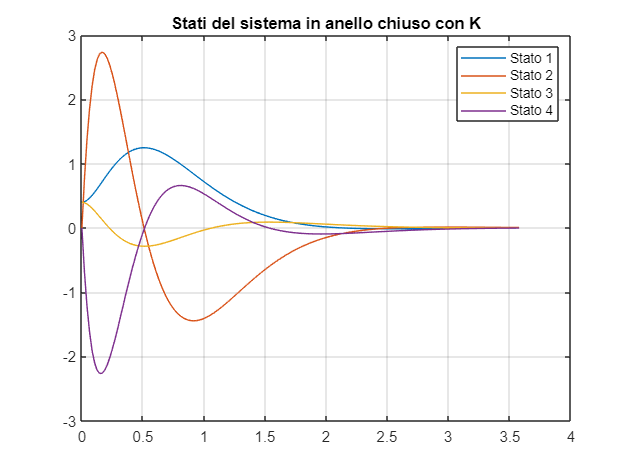

figure;
plot(T, X(:,1), T, X(:,2), T, X(:,3), T, X(:,4))
legend("Stato 1", "Stato 2", "Stato 3", "Stato 4")
title("Stati del sistema in anello chiuso con K")
grid on;

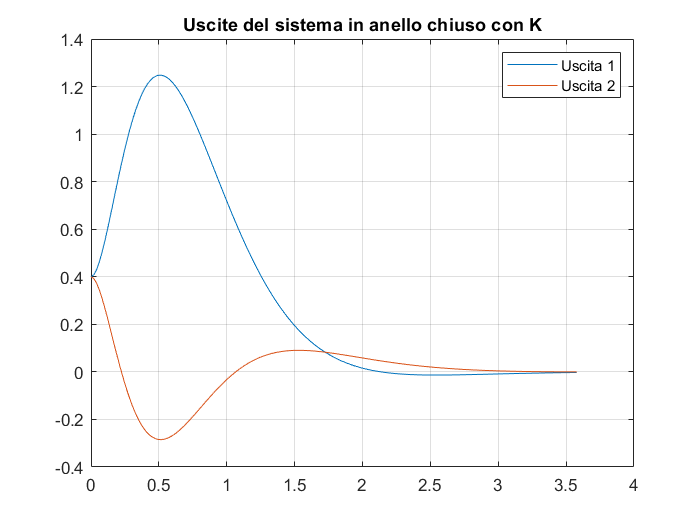


figure;
plot(T, Y(:,1), T, Y(:,2))
legend("Uscita 1", "Uscita 2")
title("Uscite del sistema in anello chiuso con K")
grid on;